# Linear Quadratic Optimal Control

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

Linear Quadratic Optimal Control (LQOC) is a collective term for a class of optimal control problems involving a linear input-state-output system and a cost functional that is a quadratic form of the state and the input. The control action is obtained by minimization of this cost functional over a given class of input functions. The optimal input depends on the feedback of the current state and thus LQOC also represents a **State Feedback Control strategy**. LQOC assumes availability of full information of state, either through direct measurement of all states or via state estimation methods such as the Kalman Filter. 

In this lesson, we will start from the finite horizon MPC problem without bound constraints and move on to an infinite horizon problem, which is nothing but the classical LQOC problem. We will learn about the Finite Horizon and Infinite Horizon formulation of linear quadratic regulator (LQR). 

**Learning Objectives**

- To develop the finite and infinite horizon LQR formulations

- To solve the finite horizon optimization problem using Bellman's Method of Backward Dynamic Programming

- Derive Algebraic Riccati Equations that solves the infinite horizon problem 

## Linear Quadratic Optimal State Regulator (LQR)

In the [last module](matlab:open('../3. Linearized Models for MPC Formulation/L01_FromDynamicModeltoPredictiveOptimalControl.mlx')), we started our journey by formulating controller as an optimization problem subject to nonlinear ODE constraints and operating constraints and gradually introduced different simplifications to make the problem tractable in the real time. At the end of the module, we introduced the[ moving horizon formulation LMPC](matlab:open('../3. Linearized Models for MPC Formulation/L05_MPCReformulationusingLinearPerturbationModel.mlx')), which used linear perturbation model of the form 

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$	-------------------(1)

where  $x\in R^n$ represents state variables and $u\in R^{m}$ represents manipulated inputs. The difficulty with the constrained LMPC formulation is that we cannot solve the resulting problem analytically. We need to use a numerical solution technique to implement the controller. In fact, even when the model used is linear, the resulting controller is a nonlinear controller due to presence of bound constraints on manipulated inputs and states. What if we decide to remove all bound constraints, is the resulting optimization problem amenable to the analytical treatment? 

Let us assume that process or system evolves as equation (1) and is perfectly known. Now consider the LMPC problem without the bound constraints and with modification that we let the prediction horizon to be infinity, i.e. 

 $u^* \left(k\right),\ldotp \ldotp \ldotp \ldotp ,u^* \left(k+p-1\right)\ldotp \ldotp \ldotp \ldotp =\underset{u\left(k\right),\ldotp \ldotp \ldotp \ldotp ,u\left(k+p-1\right)\ldotp \ldotp \ldotp \ldotp \ldotp }{\arg \;m\textrm{in}}$$\sum_{j=0}^{\infty } \left\lbrack {z\left(k+j+1\right)}^T W_x z\left(k+j+1\right)\right\rbrack +\left\lbrack {u\left(k+j\right)}^T W_u u\left(k+j\right)\right\rbrack$ -----------(2)

Subject to system dynamics 


$$z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j\right)\;\;\;\;\textrm{for}\;j=0,1,\ldotp \ldotp \ldotp \;\textrm{with}\;\textrm{initial}\;\textrm{condition}\;z\left(k\right)=x\left(k\right)$$


Since we have chosen to solve an infinite horizon problem in the moving window framework, without loss of generality, we translate the time coordinate to the current time and restate this problem as follows **(LQOC-inf**) 

 $\left\lbrace u^* \left(0\right),\ldotp \ldotp ,u^* \left(k\right),\ldotp \ldotp \ldotp \right\rbrace =\underset{u\left(0\right),\ldotp \ldotp \ldotp \ldotp ,u\left(k\right)\ldotp \ldotp \ldotp }{\arg \;m\textrm{in}}$$\sum_{k=0}^{\infty } \left\lbrack {x\left(k\right)}^T W_x x\left(k\right)\right\rbrack +\left\lbrack {u\left(k\right)}^T W_u u\left(k\right)\right\rbrack$ ---------(3)

Subject to system dynamics 


$$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)\;\;\textrm{for}\;j=0,1,\ldotp \ldotp \;\textrm{with}\;\textrm{initial}\;\textrm{condition}\;x\left(0\right)$$


To make this problem mathematically tractable, let us consider a consider the following  finite time reformulation of this problem (LQOC-N) 

$\begin{array}{l}
\left\lbrace u^* \left(0\right),\ldotp \ldotp ,u^* \left(N\right)\right\rbrace =\overset{\min }{u\left(0\right),\ldotp \ldotp \ldotp \ldotp u\left(N-1\right)} \left\lbrace {x\left(N\right)}^T W_N x\left(N\right)+\sum_{k=0}^{N-1} \left\lbrack {x\left(k\right)}^T W_x x\left(k\right)+{u\left(k\right)}^T W_u u\left(k\right)\right\rbrack \right\rbrace \\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{Subject}\;\textrm{to}\;\\
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)\;\;\;\textrm{with}\;\textrm{initial}\;\textrm{condition}\;x\left(0\right)
\end{array}$-------(4)

where $N$ is some large number. Once we develop a solution for this problem, we can let $N\to \infty$ for deriving the solution for the infinite horizon problem. Note that we have separated the final term and included ${x\left(N\right)}^T W_N x\left(N\right)$ where $W_N$ is a +ve definite ***terminal weighing matrix***.  Such a LQR formulation is often referred to as the **finite time-to-go **where the deviation from the origin at current instant $k$ is evaluated from instant $k$ up to instant $k+N$ and we seek those control input input sequence  $u\left(k\right),\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp u\left(k+N-1\right)$ that minimize finite horizon cost. 

One possible way to solve LQOC-N is to take the approach we adopted while deriving closed form control law using unconstrained LMPC formulation (refer to [Lesson 5 in Module 3](matlab:open('../3. Linearized Models for MPC Formulation/L05_MPCReformulationusingLinearPerturbationModel.mlx'))). However, if $N$ is large, then the stacked matrices can be of very large dimension and the resulting problem can be relatively difficult to solve. Moreover, the solution for $N\to \infty$, which is of primary interest to us, cannot be derived through this route. We use an elegant mathematical tool, Bellman's Dynamic Programming, to solve the finite and infinite dimensional problems. 

## **Solving Finite Time-to-Go Problem using Bellman's Dynamic Programming**

Bellman's backward dynamic programming is used to solve the Finite Time-to-Go problem analytically. The basis idea is to start optimization from time $k=N$ and work backwards in time. We solve problem at instant $k$ by assuming that problem up to time $k-1$ has been solved optimally. 

Let us define  $S(N)=W_{N}$ and a $J\left(k\right)$ as optimum over time window $\left\lbrack k,N\right\rbrack$ 

$\overset{\min }{J\left(k\right)=u\left(k\right),\ldotp \ldotp \ldotp \ldotp u\left(N-1\right)} \left\lbrace {x\left(N\right)}^T W_N x\left(N\right)+\sum_{i=k}^{N-1} \left\lbrack {x\left(i\right)}^T W_x x\left(i\right)+{u\left(i\right)}^T W_u u\left(i\right)\right\rbrack \right\rbrace$  ---------(5)

Thus, for $k=N$, we have

$J(N)=x(N)^{T}W_{N}x(N) = x(N)^{T}S(N)x(N) $  ------------(6)

Note that, since we assume that problem up to  $k=N-1$ has been solved optimally, optimal $u\left(N-1\right)$ is known. Thus, substituting for system dynamics, $x\left(N\right)=\Phi x\left(N-1\right)+\Gamma u\left(N-1\right),\textrm{in}\;$ $J\left(N\right)$, optimal $J\left(N\right)$is 

$J(N)  = [\Phi x(N-1)+\Gamma u(N-1)]^{T}S(N)[\Phi x(N-1)+\Gamma u(N-1)]
$-------------(7)

Now, let us move backward in time to $k=N-1$

$J\left(N-1\right)=\min_{u\left(N-1\right)}${${x(N-1)^{T}W_{x}x(N-1)+u(N-1)^{T}W_{u}u(N-1)+J(N)}$}--------(8)

Substituting for$J\left(N\right)$in expression for $J\left(N-1\right)$and rearranging, we can write 

$J\left(N-1\right)=\min_{u\left(N-1\right)} \left\lbrace J_{\textrm{xx}} \left(N-1\right)+J_{\textrm{xu}} \left(N-1\right)+J_{\textrm{ux}} \left(N-1\right)+J_{\textrm{uu}} \left(N-1\right)\right\rbrace$   ----------(9)


$${J_{\textrm{xx}} \left(N-1\right)=x\left(N-1\right)}^T \left\lbrack W_x +\Phi^T S\left(N\right)\Phi \right\rbrack x\left(N-1\right)\;,\;\;\;\;\;\;\;\;\;\;\;\;\;J_{\textrm{xu}} \left(N-1\right)=\;{x\left(N-1\right)}^T \Phi^T S\left(N\right)\Gamma u\left(N-1\right)$$



$${J_{\textrm{ux}} \left(N-1\right)=u\left(N-1\right)}^T \Gamma^T S\left(N\right)\Phi x\left(N-1\right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;J_{\textrm{uu}} \left(N-1\right)={u\left(N-1\right)}^T \left\lbrack \Gamma^T S\left(N\right)\Gamma +W_u \right\rbrack u\left(N-1\right)$$


Note that the first term $J_{\textrm{xx}} \left(N-1\right)$ in $J\left(N-1\right)$ cannot be influenced by $u\left(N-1\right)$. We solve the problem of minimizing the last three terms in $J\left(N-1\right)$ which contain the term $u\left(N-1\right)$. Note that $J_{\textrm{xu}} \left(N-1\right)\;\;\textrm{and}\;J_{\textrm{ux}} \left(N-1\right)$ are linear terms in $u\left(N-1\right)$ while $J_{\textrm{uu}} \left(N-1\right)$ is a quadratic term in $u\left(N-1\right)$. Thus, this equation can be solved using the method of competing squares. 

Consider a scalar quadratic function which is similar to equation (9)

$F\left(u\right)=u^T \textrm{Au}+\zeta^T u+u^T \zeta$ -------(10)

where $A$ is a positive definite matrix. Adding and subtracting $\zeta^T A^{-1} \zeta$ on the R.H.S. of equation (10) 

$F(u) = u^{T}Au+\zeta^{T}u+u^{T}\zeta+\zeta^{T}A⁻¹\zeta - \zeta^{T}A⁻¹\zeta
	 = (u+A⁻¹\zeta)^{T}A(u+A⁻¹\zeta) - \zeta^{T}A⁻¹\zeta$---------(11)

The first term on the right hand side in the above equation is always non-negative. This implies that minimum of $F\left(u\right)$ with respect to $u$ is attained at $u=\textrm{A⁻¹}\zeta$ and its minimum value is 

$F_{min}(u)=-\zeta^{T}A⁻¹\zeta$--------(12)

Returning to the minimization problem at hand, with some rearrangement, we see that

$	A \equiv  [\Gamma ^{T}S(N)\Gamma +W_{u}]$    and     $\zeta \equiv  \Gamma ^{T}S(N)\Phi x(N-1)
$

and the optimal solution can be expressed as

$u(N-1)  = -G(N-1)x(N-1) $-------------(13 a)

where

$G\left(N-1\right)={\left(W_u +\Gamma^T S\left(N\right)\Gamma \right)}^{-1} \Gamma^T S\left(N\right)\Phi$-----(13 b)

which gives minimum value of the loss function, 

$J(N-1)=x(N-1)^{T}S(N-1)x(N-1)$-----------(14 a)

where

$S(N-1)=\Phi ^{T}S(N)\Phi +W_{x}-G(N-1)^{T}[W_{u}+\Gamma ^{T}S(N)\Gamma ]G(N-1) $--------(14 b)

Similar arguments yield the next optimization problem

$J\left(N-2\right)=\min_{u\left(N-2\right)}${${x(N-2)^{T}W_{x}x(N-2)+u(N-2)^{T}W_{u}u(N-2)+J(N-1)}$}---------(15)

This minimization problem is similar to the earlier optimization problem, but with the time argument shifted. As a consequence, the solution can be constructed in an identical manner by repeating the procedure backward in time. 

    $u(N-2)  = -G(N-2)x(N-2) $    ---------(16 a)

$G\left(N-2\right)={\left(W_u +\Gamma^T S\left(N-1\right)\Gamma \right)}^{-1} \Gamma^T S\left(N-1\right)\Phi$    --------(16 b)

$S(N-2)=\Phi ^{T}S(N-1)\Phi +W_{x}-G(N-2)^{T}[W_{u}+\Gamma ^{T}S(N-1)\Gamma ]G(N-2) $  ------(17) 

By induction, the optimal gain matrix and manipulated input at the $k^{\textrm{th}}$ instant can be computed as follows 

$G\left(k\right)={\left(W_u +\Gamma^T S\left(k+1\right)\Gamma \right)}^{-1} \Gamma^T S\left(k+1\right)\Phi$----------(18 a)    


$$S(k)=\Phi ^{T}S(k+1)\Phi +W_{x}-G(k)^{T}[W_{u}+\Gamma ^{T}S(k+1)\Gamma ]G(k) $$


$S(k)=[\Phi -\Gamma G(k)]^{T}S(k+1)[\Phi -\Gamma G(k)]+W_{x}+G(k)^{T}W_{u}G(k) 
$-------(18b)

$u\left(k\right)=-G\left(k\right)x\left(k\right)$--------------------------------(19)

Observe that the application of Bellman's backward dynamic programming gives rise to a** time varying state feedback control law**. Equations (18a) and (18b) are called as the **discrete time dynamic Riccati equations (DDRE)**. The DDRE is solved backwards in time starting from $N,N-1,\ldotp \ldotp \ldotp \ldotp 1$ with $S(N)=W_{N}$. Since the matrices  $S(N)=W_{N}$ and  $W_u$ are chosen to be positive definite and symmetric, the sequence of matrices $S\left(k\right)$ is positive definite and symmetric. This condition guarantees optimality at each stage.  

    Thus, we have an elegant method to construct optimal manipulated input sequence for large $N$. Note that $N$should be pre-decided or known a-priori and the entire sequence of gain matrices have to be saved for implementing the control sequence. Such finite horizon control can be used in finite time repetitive maneuvers, where a specific goal needs to be achieved within a limited time frame such as a robotic arm reaching a target point quickly in a manufacturing facility. 

## Example: Finite Horizon Control of Quadruple Tank Process

**Minimum Phase System Behaviour**

Consider the linearized mechanistic model for Quadruple Tank System obtained using sampling time of 4 seconds. Following are the model matrices for the [ Minimum Phase Operating Point.](matlab:open('../3. Linearized Models for MPC Formulation/L02_Linearization_of_noninear_Models.mlx'))


$$\Phi =\left\lbrack \begin{array}{cccc}
0\ldotp 9379 & 0 & 0\ldotp 1560 & 0\\
0 & 0\ldotp 9568 & 0 & 0\ldotp 1217\\
0 & 0 & 0\ldotp 8388 & 0\\
0 & 0 & 0 & 0\ldotp 8755
\end{array}\right\rbrack$$
                  
$$\Gamma =\left\lbrack \begin{array}{cc}
0\ldotp 3225 & 0\ldotp 0155\\
0\ldotp 0078 & 0\ldotp 2458\\
0 & 0\ldotp 1756\\
0\ldotp 1169 & 0
\end{array}\right\rbrack$$


### **Non-Minimum Phase System Behaviour**

The linearized mechanistic model for Quadruple Tank System, at sampling time of 4 seconds for[ Non-Minimum Phase Operating Point.](matlab:open('../3. Linearized Models for MPC Formulation/L03_Local_Linear_Model_QTank_process.mlx'))

Here, one transmission zero is outside the unit circle. This system is relatively difficult to control. 


$$\Phi =\left\lbrack \begin{array}{cccc}
0\ldotp 9383 & 0 & 0\ldotp 0950 & 0\\
0 & 0\ldotp 9574 & 0 & 0\ldotp 0668\\
0 & 0 & 0\ldotp 9019 & 0\\
0 & 0 & 0 & 0\ldotp 9318
\end{array}\right\rbrack$$
                  
$$\Gamma =\left\lbrack \begin{array}{cc}
0\ldotp 1869 & 0\ldotp 0152\\
0\ldotp 0076 & 0\ldotp 1368\\
0 & 0\ldotp 2947\\
0\ldotp 2160 & 0
\end{array}\right\rbrack$$



$$C=\left\lbrack \begin{array}{cccc}
0\ldotp 5 & 0 & 0 & 0\\
0 & 0\ldotp 5 & 0 & 0
\end{array}\right\rbrack$$


Let us assume that the initial state of the system is different from the equilibrium point and we are interested in bringing the system to the equilibrium point in 100 samples, i.e. N= 100. Let the weighting matrices be chosen as 


$$W_N ={100\;\mathbf{I}}_4 ,\;W_x ={10\;\mathbf{I}}_4 \;\;\textrm{and}\;\;W_u =0\ldotp 01{\mathbf{I}}_2$$


where ${\mathbf{I}}_n \;$ represents $n\times n$ identity matrix. Note that we would like to bring the system to the origin starting from any arbitrary initial condition, $x\left(0\right)$. This may require large input moves. Thus, we have chosen the weighting matrix$W_u$ to be small relative to the weighting on states, i.e.  Let us compute this in MATLAB

### ** Quadruple Tank System control using DDRE solution **

Quadruple tank system  is represented by the $\Phi$ and $\Gamma$ are given as  above and the  LQOC tuning matrices are set as 


$$W_N ={100\;\mathbf{I}}_4 ,\;W_x ={10\;\mathbf{I}}_4 \;\;\textrm{and}\;\;W_u =0\ldotp 01{\mathbf{I}}_2$$


Controller is developed by solving DDRE backward in time. Let us now check how controller works under ideal conditions (ideal linear plant simulation)  

clear all 
close all
global QTank U_k D_k

%Set_Graphics_Parameters

**Task 1: **Set the operating point to Minimum Phase

operating_pt=2;

% Load quadruple tank parameters and steady state 
if operating_pt==1
     fprintf('\n\t Quadruple Tank System(Minimum Phase): Linear Quadratic Optimal Control Simulation \n') ;
load QTank_MinPhase_Model
else
     fprintf('\n\t Quadruple Tank System(Non-Minimum Phase): Linear Quadratic Optimal Control Simulation \n') ;
 load QTank_NonMinPhase_Model 
end


	 Quadruple Tank System(Non-Minimum Phase): Linear Quadratic Optimal Control Simulation 


% Initialization of linear discrete time model for plant simulation 
phy = QTank.phy ;
gam = QTank.gama_u  ;
[n_st,n_ip] = size(gam) ;


**LQOC Tuning Matrices**

The weighting matrices are set as


$$W_N =\left\lbrack \begin{array}{cccc}
\alpha_{\textrm{N1}}  & 0 & 0 & 0\\
0 & \alpha_{\textrm{N2}}  & 0 & 0\\
0 & 0 & \alpha_{\textrm{N3}}  & 0\\
0 & 0 & 0 & \alpha_{\textrm{N4}} 
\end{array}\right\rbrack ,\;W_x ==\left\lbrack \begin{array}{cccc}
\alpha_1  & 0 & 0 & 0\\
0 & \alpha_2  & 0 & 0\\
0 & 0 & \alpha_3  & 0\\
0 & 0 & 0 & \alpha_4 
\end{array}\right\rbrack \;\;\textrm{and}\;\;W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$$


**Task 2:** Adjust the sliders for weighting matrices to give weighting to the levels. Let us say that regulation of levels in Tank 1 and Tank 2 is more important than regulation of levels in Tank 3 and Tank 4.  This can be communicated to the controller by choosing a state weighting matrix as follow 

alpha(1) =15;  alpha(2) = 10;
alpha(3) =2;  alpha(4) = 2; 
disp('State weighting matrix')

State weighting matrix


Wx= diag(alpha)   % Create a diagonal weighting matrix 

Wx =     15     0     0     0
     0    10     0     0
     0     0     2     0
     0     0     0     2



disp('Input weighting matrix')

Input weighting matrix


beta(1) =1;  beta(2) =1;
Wu= diag(beta) 

Wu =      1     0
     0     1


disp('Terminal State weighting matrix')

Terminal State weighting matrix


alfa_N(1) =100;
alfa_N(2) =100;
alfa_N(3) =100;
alfa_N(4) =100;
WN = diag(alfa_N)

WN =    100     0     0     0
     0   100     0     0
     0     0   100     0
     0     0     0   100


N = 100 ;   

u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
u_L = [0 0]' - QTank.Us ;  % Steady state inputs are [3 3] for nonminimum phase and [3.15 3.15] for non-minimum phase

% Initialize data structures for saving LQR related matrices 
for k = 1 : N 
   LQR(k) = struct('S',zeros(n_st,n_st), 'G',zeros(n_ip,n_st)) ;
end
LQR(N).S = WN ;

**Controller Implementation**

DDRE is solved backward in time for 100 samples and a time varying control law $u(k)=-G(k) x(k)$ is used.**  LQR** is the structure where the controller gain and the solution of DDRE is stored. Let us now check how controller works for nonlinear plant simulation. Q tank dynamics are saved in a function **QTank_Dynamics.m**, and the nonlinear ODEs are solved using MATLAB ODE solver ode45, as seen in earlier exercises. The initial state is set as


$$x\left(k\right)=\left\lbrack 2\;-2\;\;\;1\;-1\right\rbrack$$


**uk_bound_constraints **is a function used to impose $u\left(k\right)$ bound constraints in an Ad-hoc manner.

% Solve DDRE backward in time
for k = N-1:-1:1
    LQR(k).G =inv(Wu + gam'*LQR(k+1).S *gam) * gam' * LQR(k+1).S * phy;
    phy_cl = (phy-gam*LQR(k).G) ;
    LQR(k).S= phy_cl'*LQR(k+1).S* phy_cl + Wx + LQR(k).G'*Wu*LQR(k).G ;
end

% Check how controller works under ideal conditions (ideal linear plant simulation)  
xk = zeros(n_st,N);

**Task 3:** Specify initial condition away from the steady state 

% Specify initial condition away from the steady state 
x0(1) =4;  x0(2) = -4;
x0(3) = 2;  x0(4) = -2; 
xk(:,1) =  x0' ;  % Specify an initial state is away from the origin 
Xk(:,1) = xk(:,1)+QTank.Xs;
uk = zeros(n_ip,N) ;
kT = zeros(1,N) ;  % Sampling instant 

norm_delG = zeros(N-1,1) ;
eig_SK = zeros(n_st, N) ;

**Task 4:** Plant simulation from instant $k$to $k+1$ can be done either by solving nonlinear ODE using MATLAB solver or by using a linear discrete time model. Set the Plant _Sim to Linear.

Plant_Sim =1  ; 

for k = 1:N-1
    kT(k) = (k-1);
    % Controller implementation at instant k
    uk(:,k) = - LQR(k).G * xk(:,k) ;

    % Impose uk bound constraints
    uk_clipped = uk_bound_constraints( uk(:,k),  u_L, u_H ) ;
    uk(:,k) = uk_clipped' ;

       if (Plant_Sim )
        % Linear plant simulation
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k)  ;
    else
        % Nonlinear plant simulation
        U_k = QTank.Us + uk(:,k) ;
        D_k =  QTank.Ds ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end

    % Calculations for analysis
    norm_delG(k) = norm(LQR(k).G-LQR(k+1).G) ;
    eig_Sk(:,k) = sort(eig(LQR(k).S)) ;
end
uk(:,N) = uk(:,N-1) ;
kT(N) = N ; 
eig_Sk(:,N) = sort(eig(LQR(N).S)) ; 



**Display Simulation Results**

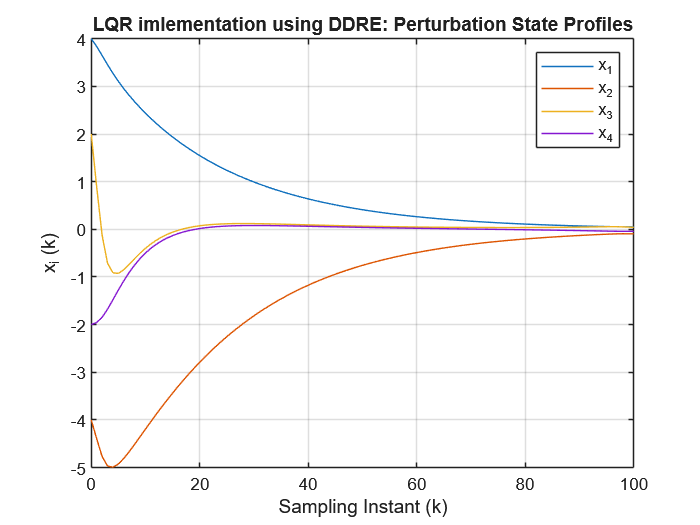

figure, plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)'), title('LQR imlementation using DDRE: Perturbation State Profiles')
legend('x_1', 'x_2', 'x_3', 'x_4')

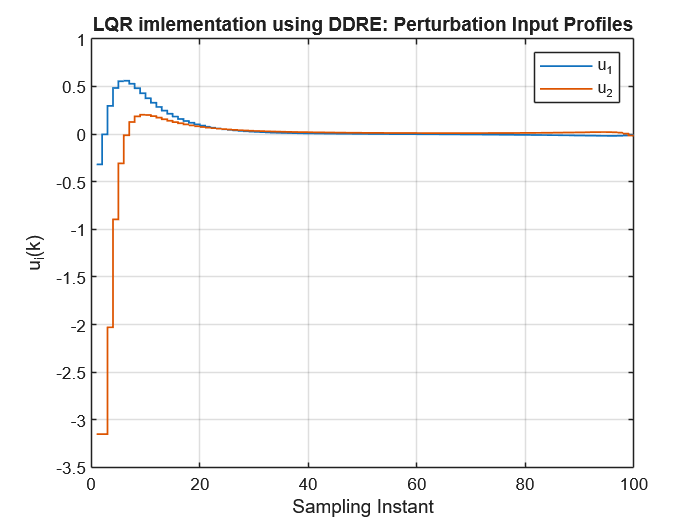

figure, stairs(uk', 'LineWidth',1), grid
xlabel('Sampling Instant'), ylabel('u_i(k)'), title('LQR imlementation using DDRE: Perturbation Input Profiles')
legend('u_1', 'u_2')

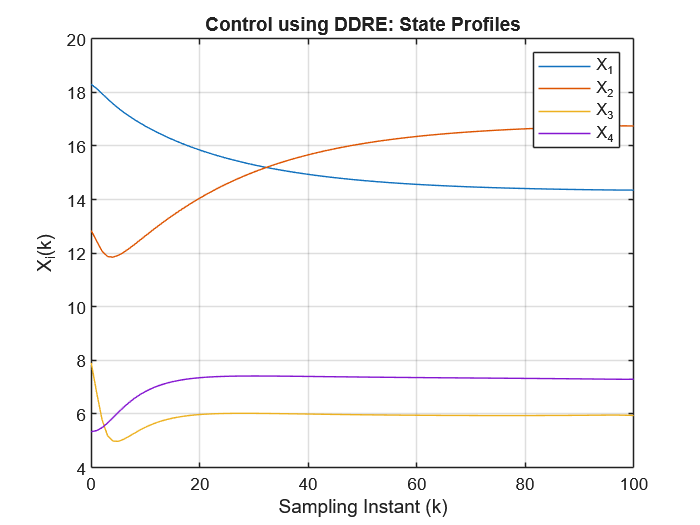

Xk = QTank.Xs + xk;
 Uk = QTank.Us + uk ;
figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('X_i(k)'), title('Control using DDRE: State Profiles')
legend('X_1', 'X_2', 'X_3', 'X_4')

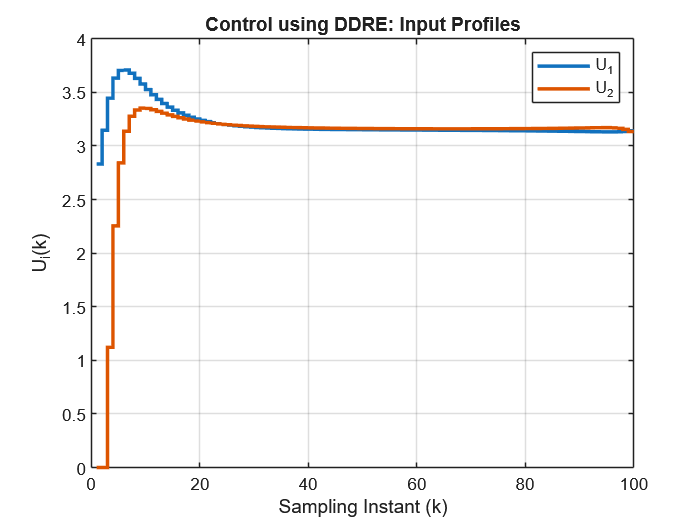

figure, stairs(Uk', 'LineWidth',2), grid
xlabel('Sampling Instant (k)'), ylabel('U_i(k)'), title('Control using DDRE: Input Profiles')
legend('U_1', 'U_2')

**LQR implementation using DDRE: Behavior of Gain Matrices**

To observe how the LQR gain varies as a function of time, we compute the norm of gain as 


$$\left\|\Delta G\left(k\right)\right\|=\left\|G\left(k\right)-G\left(k+1\right)\right\|$$


We have used MATLAB function [norm](https://in.mathworks.com/help/matlab/ref/norm.html),  [`n`](https://in.mathworks.com/help/matlab/ref/norm.html#bt0y64b-1-n) `= norm(`[`X`](https://in.mathworks.com/help/matlab/ref/norm.html#bt0y64b-1-X)`)` returns the 2-norm or maximum singular value of matrix `X. `It is plotted below.

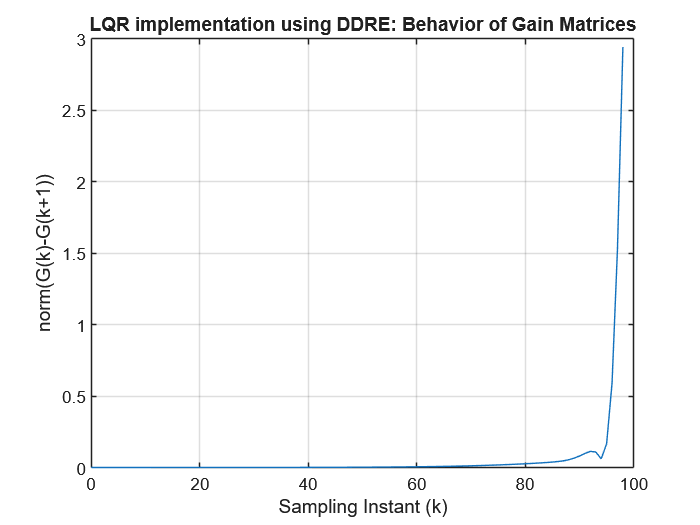

figure, plot(kT(1:N-1), norm_delG), grid
xlabel('Sampling Instant (k)'), ylabel('norm(G(k)-G(k+1))'), title('LQR implementation using DDRE: Behavior of Gain Matrices')

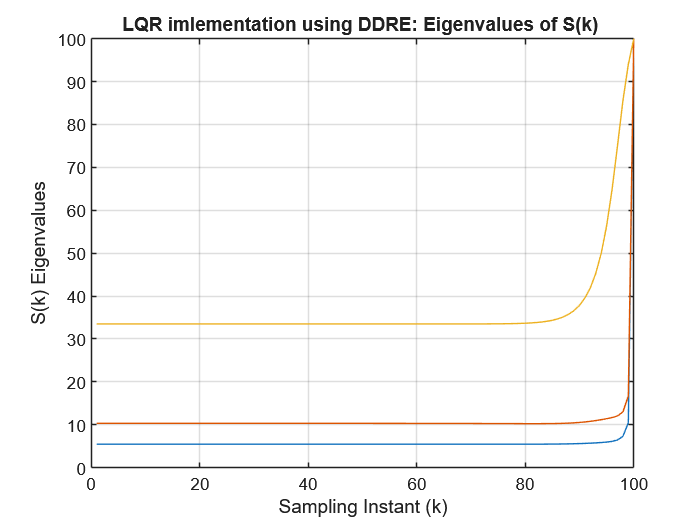

figure, plot(eig_Sk'), grid
axis([0 N 0 max(alfa_N)])
xlabel('Sampling Instant (k)'), ylabel('S(k) Eigenvalues'), title('LQR imlementation using DDRE: Eigenvalues of S(k) ')

Observe the results of simulation. From the plots it can be seen that starting from some arbitrary initial state, the states are brought to their steady state values  $\left(13\ldotp 1699,14\ldotp 5390,1\ldotp 9753,2\ldotp 0297\;\right)$ and the inputs also settle at the corresponding steady state values. The controller gain almost becomes constant at $k=60$. All eigen values of $S\left(k\right)$ are positive. 

**Task 5:** Change the operating point to Non-minimum phase and observe the results. The steady state state variables are  steady state values $\left(13\ldotp 3553,\;14\ldotp 9479,\;5\ldotp 2997,\;6\ldotp 1041\right)$ 

**Closed loop performance index(PI)**

Let us define a closed loop performance index(PI) motivated by the LQR cost function as follows 


$$\textrm{PI}\equiv \sum_{k=0}^N \left\lbrack {x\left(k\right)}^T W_x x\left(k\right)+{u\left(k\right)}^T W_u u\left(k\right)\right\rbrack$$


where $N$ represents the simulation time. This PI can be used to compare performances of controllers that we developed in this lesson. 

fval_LQRN = 0 ;
for k = 1:N
    fval_LQRN = fval_LQRN + xk(:,k)' * Wx* xk(:,k) ;
    fval_LQRN = fval_LQRN + uk(:,k)' * Wu* uk(:,k) ;
end
fval_LQRN

fval_LQRN = 7.0828e+03

% Function to impose input bounds

function uk_clipped = uk_bound_constraints( u_k, u_L, u_H )

% Ad-hoc implementation of bound constraints

uk_clipped = u_k ; 

if ( u_k(1) <= u_L(1) )   % Impose input constraints on uk(1)
    uk_clipped(1) = u_L(1) ;
elseif ( u_k(1) >= u_H(1) )
    uk_clipped(1) = u_H(1) ;
end
if ( u_k(2) <= u_L(2) ) % Impose output constraints on uk(2)
    uk_clipped(2) = u_L(2) ;
elseif ( u_k(2) >= u_H(2) )
    uk_clipped(2) = u_H(2) ;
end

end

## Infinite Horizon Quadratic Optimal Control

 Saving gain matrices over large time is not a practical solution when $N$ is large. The last two plots reveal interesting features of LQOC. Note that $\|G\left(k\right)-G\left(k+1\right)\|\to 0$ as $k\to 0$ starting from $N$. In fact, $G\left(k\right)$ changes only for 10 to 12 samples when moving backward in time starting from  $N=100\ldotp$ Let us take a look at some matrices starting from $k=99$ for the minimum phase case. (This can be observed by checking the variable LQR.G). Note that we have used the *MATLAB notation* for representing the gain matrices $G\left(k\right)$ here when we select 


$$W_N ={100\;\mathbf{I}}_4 ,\;W_x ={10\;\mathbf{I}}_4 \;\;\textrm{and}\;\;W_u =0\ldotp 01{\mathbf{I}}_2$$



$$G\left(99\right)=\left\lbrack 2\ldotp 5653,-0\ldotp 0813,0\ldotp 3044,0\ldotp 8882;\;-0\ldotp 027826307365143,2\ldotp 5673,1\ldotp 6373,0\ldotp 2143\right\rbrack$$
  


$$G\left(95\right)=\left\lbrack 2\ldotp 5894,0\ldotp 06118,0\ldotp 1329,0\ldotp 7767;\;0\ldotp 06499,3\ldotp 0019,1\ldotp 0623,0\ldotp 00109\right\rbrack$$



$$G\left(90\right)=\left\lbrack 2\ldotp 5725,0\ldotp 0203,0\ldotp 1819,0\ldotp 8183;\;0\ldotp 0166,2\ldotp 8823,1\ldotp 2060,0\ldotp 1199\right\rbrack$$



$$G\left(50\right)=\left\lbrack 2\ldotp 5700,0\ldotp 0113,0\ldotp 1929,0\ldotp 8245;\;0\ldotp 01023,2\ldotp 854,1\ldotp 2399,0\ldotp 1352\right\rbrack$$



$$G\left(1\right)=\left\lbrack 2\ldotp 5700,0\ldotp 0113,0\ldotp 1929,0\ldotp 8245;\;0\ldotp 01025,2\ldotp 8543,1\ldotp 2399,0\ldotp 1351\right\rbrack$$


Note that $G\left(k\right)$ becomes almost constant for $k<80$, which is also seen in $\|G\left(k+1\right)-G\left(k\right)\|$ v/s k plot. Also, progression eigenvalues of S(k) as function of time shows that, while the eigenvalues always remain +ve, they remain constant between $k=0$ and $k=70$ and change only between 70 to 100. Thus, when LQOC is used for continuously operated systems, $N$  is large, and it may be possible to ignore variations in $G\left(k\right)$ close to $k=N$ and we can work with a fixed gain controller, $G=G\left(1\right)$. 

Note that DDRE is a difference equation in time. Does it have an equilibrium (or a steady state) solution as $N\to \infty$? When $N$ becomes large, we can get the Infinite horizon formulation LQOC-inf**.** If such an equilibrium solution exists and $G\left(k\right)\to G_{\infty }$ for $k\ll N$, then we can use a fixed control law 

$u(k)=-G_{\infty }x(k)$ -----(20)

starting from $k=0$ instead of using time varying controller gain matrices. When horizon $N$ becomes large and the system matrices obey certain regularity conditions, $S\left(k\right)$ tends to a constant matrix, $S(k)\to S_{\infty }$, which can be computed by solving the **Discrete-Time Algebraic Riccati Equation (DARE)**

$G_{\infty } ={\left(W_u +\Gamma^T S_{\infty } \Gamma \right)}^{-1} \Gamma^T S_{\infty } \Phi$-------(21)

	$S_{\infty }=[\Phi -\Gamma G_{\infty }]^{T}S_{\infty }[\Phi -\Gamma G_{\infty }]+W_{x}+G_{\infty }^{T}W_{u}G_{\infty } $-------------(22)

This ARE has several solutions. What are the regularity conditions system matrices need to satisfy for a unique solution to exist? The first condition is called **controllability. **This is a fundamental property of the discrete linear system (1). Given initial state $x\left(0\right)$ and input sequence $u\left(0\right),u\left(1\right),\ldots,$ the discrete system evolves according to  

 $x\left(1\right)=\Phi x\left(0\right)+\Gamma u\left(0\right)$  ------ (23)

$x\left(2\right)=\Phi x\left(1\right)+\Gamma u\left(1\right)$=$\Phi^2 x\left(0\right)+\Phi \Gamma u\left(0\right)+\Gamma u\left(1\right)$  -----(24)

.......=......

$x\left(n\right)=\Phi^n x\left(0\right)+\Phi^{n-1} \Gamma u\left(0\right)+\ldotp \ldotp \ldotp +\Phi \Gamma u\left(n-2\right)+\Gamma u\left(n-1\right)$ ------(25)

Here $n$ represents the order of the state dimension. Can we move the system state from and arbitrary initial condition $x\left(0\right)$ to some arbitrary state, say $x_f \in R^n$, in $n$ steps?  Setting $x\left(n\right)=x_f$ and rearranging equation (25), we can arrive at the following equation that can answer this question. 

$\left\lbrack \begin{array}{cccc}
\Gamma  & \Phi \Gamma  & \ldotp \ldotp \ldotp \ldotp  & \Phi^{n-1} \Gamma 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u\left(n-1\right)\\
u\left(n-2\right)\\
\ldotp \ldotp \ldotp \ldotp \\
u\left(0\right)
\end{array}\right\rbrack =x_f -\Phi^n x\left(0\right)$  ------(26)

 This is possible only when the **controllability matrix**, $W_C$, defined as

 $W_C =\left\lbrack \begin{array}{cccc}
\Gamma  & \Phi \Gamma  & \ldotp \ldotp \ldotp \ldotp  & \Phi^{n-1} \Gamma 
\end{array}\right\rbrack$---------(27)

has rank equal to $n$. This property, referred to as **controllability**, is a fundamental property of the discrete time system, which plays a critical role in synthesis of state feedback controllers. 

There is one more rank condition that needs to be obeyed by system and controller matrices. Defining matrix $\Omega$ as square-root of $W_x =\Omega^T \Omega$ and matrix 

$W_O =\left\lbrack \begin{array}{c}
\Omega \\
\Omega \Phi \\
\ldotp \ldotp \ldotp \ldotp \\
\Omega \Phi^{n-1} 
\end{array}\right\rbrack$---------(28)

 this condition requires $\textrm{Rank}\left(W_O \right)=n$. This matrix is similar to the *observability* matrix.  The notion of* observability* will be introduced in the later part of the course. Thus, if  $\left(\Phi ,\Gamma \right)$ is controllable pair and if $\left(\Phi ,\Omega \right)$ is observable pair,  then there exists a unique, symmetric, non-negative definite solution to the ARE.  By selecting $W_{x} $ and $W_{u}$ appropriately, it is easy to compromise between speed of recovery and magnitude of control signals. Infinite Horizon LQOC is used in the continuously operated systems where long-term performance is prioritized, like maintaining a desired temperature and reactant concentration in a continuously operated stirred-tank reactor (CSTR) system.

Since we observe that $\|G\left(k\right)-G\left(k+1\right)\|\to 0$ as $k\to 0$, let us examine how is the closed loop behavior if we implement a fixed gain control law, $u(k)=-G(1) x(k)$ on the quadruple tank system. 

### Quadruple Tank System Infinite Horizon LQOC

Closed loop simulations using fixed gain control law $u(k)=-G(1) x(k)$.

% Quadruple Tank System (continued) 

xk = zeros(n_st,N);

**Task 6:** Specify initial condition away from the steady state 

% Specify initial condition away from the steady state 
x0(1) =4;  x0(2) = -4;
x0(3) = 2;  x0(4) = -2; 
Xk(:,1) = QTank.Xs + x0' ;  % Specify an initial state is away from the origin 
xk(:,1) =  x0';
uk = zeros(n_ip,N) ;

% Closed loop simulations using fixed gain control law 
for k = 1:N-1
    kT(k) = (k-1);
     % Controller implementation at instant k
    uk(:,k) = - LQR(1).G * xk(:,k) ;

    % Impose uk bound constraints
    uk_clipped = uk_bound_constraints( uk(:,k),  u_L, u_H ) ;
    uk(:,k) = uk_clipped' ;

    % Finding system state at instant (k+1) using process simulation 
    % xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) ;
    if (Plant_Sim )
        % Linear plant simulation
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k)  ;
    else
        % Nonlinear plant simulation
        U_k = QTank.Us + uk(:,k) ;
        D_k =  QTank.Ds ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
 end
uk(:,N) = uk(:,N-1) ;

% Compute performance index 
fval_LQRinf = 0 ;
for k = 1:N
    fval_LQRinf = fval_LQRinf + xk(:,k)' * Wx* xk(:,k) ;
    fval_LQRinf = fval_LQRinf + uk(:,k)' * Wu* uk(:,k) ;
end
fval_LQRinf

fval_LQRinf = 7.0838e+03

**Display Simulation Results**

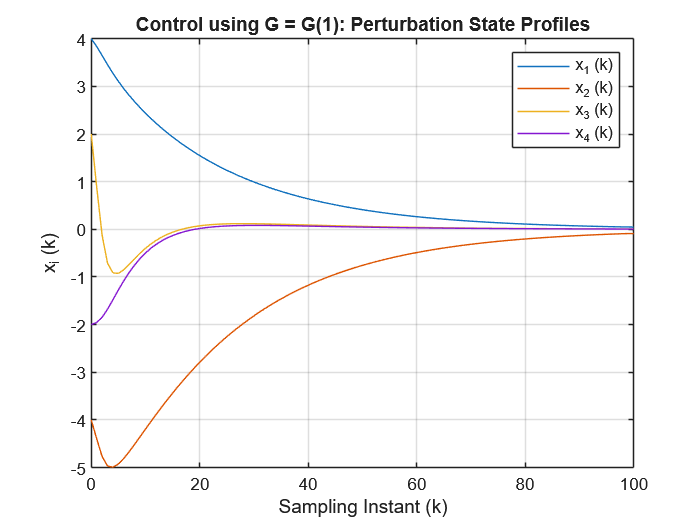

figure, plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)'), title('Control using G = G(1): Perturbation State Profiles')

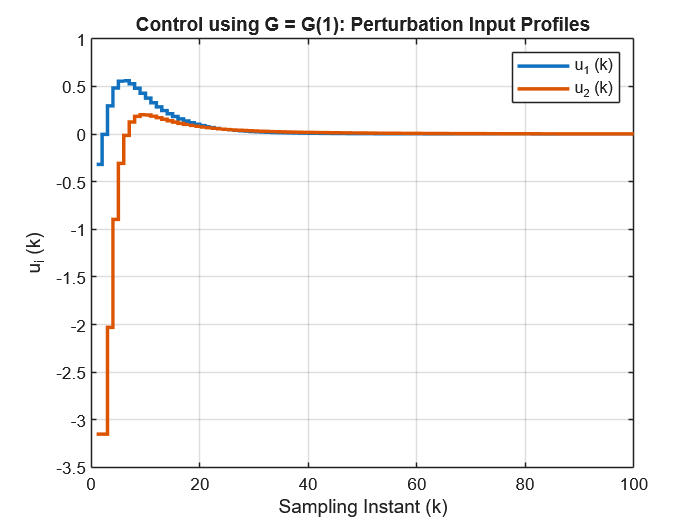

figure, stairs(uk', 'LineWidth',2), grid
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), title('Control using G = G(1): Perturbation Input Profiles')
legend('u_1 (k)', 'u_2 (k)')

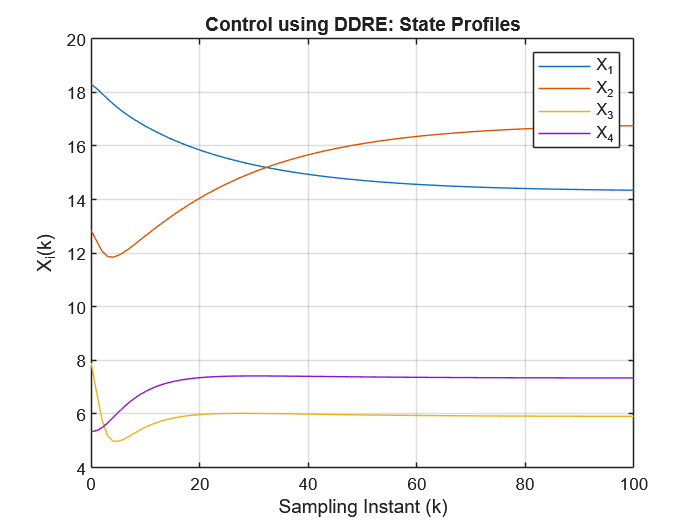

Xk = QTank.Xs + xk;
 Uk = QTank.Us + uk ;
figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('X_i(k)'), title('Control using DDRE: State Profiles')
legend('X_1', 'X_2', 'X_3', 'X_4')

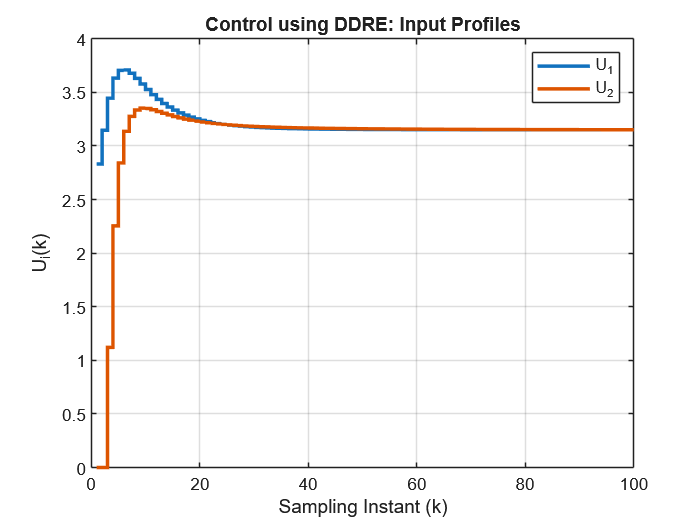

figure, stairs(Uk', 'LineWidth',2), grid
xlabel('Sampling Instant (k)'), ylabel('U_i(k)'), title('Control using DDRE: Input Profiles')
legend('U_1', 'U_2')

Behavior obtained using fixed controller $G=G\left(1\right)$ is very close to the solution obtained using time varying $G$ matrix.  Let us find the solution of ARE for the quadruple tank system. We first check whether the given system is controllable or not. MATLAB command [ctrb](https://in.mathworks.com/help/control/ref/statespacemodel.ctrb.html) is used for this. $W_c$ is the controllability matrix

% Quadruple Tank System (continued): Rank conditions  
disp('Controllability Matrix is')

Controllability Matrix is


Wc = ctrb( phy, gam ) 

Wc =     0.1873    0.0136    0.1765    0.0382    0.1663    0.0592    0.1567    0.0769
    0.0063    0.1372    0.0181    0.1320    0.0288    0.1270    0.0385    0.1222
         0    0.2963         0    0.2701         0    0.2463         0    0.2245
    0.2173         0    0.2050         0    0.1934         0    0.1825         0


disp('Rank of Controllabilty Matrix is')

Rank of Controllabilty Matrix is


rank_Wc = rank( Wc )

rank_Wc = 4

Omega_mat = sqrt( Wx )

Omega_mat =     3.8730         0         0         0
         0    3.1623         0         0
         0         0    1.4142         0
         0         0         0    1.4142


disp('Observabilty Matrix is')

Observabilty Matrix is


Wo_LQR = obsv(phy, Omega_mat) 

Wo_LQR =     3.8730         0         0         0
         0    3.1623         0         0
         0         0    1.4142         0
         0         0         0    1.4142
    3.6496         0    0.3320         0
         0    3.0430         0    0.1756
         0         0    1.2893         0
         0         0         0    1.3342
    3.4391         0    0.6155         0
         0    2.9282         0    0.3346
         0         0    1.1754         0
         0         0         0    1.2587
    3.2408         0    0.8559         0
         0    2.8178         0    0.4782
         0         0    1.0716         0


disp('Rank of Observabilty Matrix is')

Rank of Observabilty Matrix is


rank_Wo = rank( Wo_LQR )

rank_Wo = 4

 You will notice that ranks of both matrices are 4, which is equal to the state dimension. Thus, a unique solution exists for ARE in this case. Let is find the solution. This can be done using MATLAB command [**dlqr**](https://in.mathworks.com/help/control/ref/lti.dlqr.html)**.**

% Quadruple Tank System control (continued): Solving ARE 
[G_inf,S_inf, Eig_CL] = dlqr(phy, gam, Wx, Wu, zeros(n_st,n_ip)) 

G_inf =     1.5742    0.9009   -0.2275    0.9604
    1.0348    0.6234    1.1590   -0.7411


S_inf =    65.9664  -47.4172   26.3484  -38.5183
  -47.4172  100.4019  -39.9352   47.4567
   26.3484  -39.9352   24.3059  -24.8840
  -38.5183   47.4567  -24.8840   40.7834


Eig_CL =     0.9570
    0.8541
    0.5349
    0.4614


Note the controller gain matrix obtained is (for case $W_N ={100\;\mathbf{I}}_4 ,\;W_x ={10\;\mathbf{I}}_4 \;\;\textrm{and}\;\;W_u =0\ldotp 01{\mathbf{I}}_2$), **G_inf**, which is identical to $G\left(1\right)$ obtained by solving DDRE backward in time starting from $N=100$ in the first four decimals, i.e. 

LQR(1).G

ans =     1.5743    0.9008   -0.2274    0.9603
    1.0347    0.6235    1.1590   -0.7410


norm_G_inf=norm(G_inf-LQR(1).G)

norm_G_inf = 2.9401e-04

In fact, $\|G_{\infty } -G\left(0\right)\|=1\ldotp 8350*{10}^{-7} \;\textrm{and}\;\;\|S_{\infty } -S\left(0\right)\|=3\ldotp 6353\times {10}^{-5}$, i.e. DDRE with $N=100$ arrives close to the solution of ARE when the time index reaches 0 starting from 99. MATLAB function ***dlqr*** also gives eigenvalues of matrix $\left(\Phi -\Gamma G_{\infty } \right)$, which are displayed above(Eig_CL). Significance of these eigenvalues and their relationship with the closed loop stability will be discussed in the next lesson. 

## Linear Quadratic Optimal Output Regulator Design

 In many situations we are only interested in controlling certain outputs, y(k), of a discrete linear system, i.e.  

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)\;\;\;$-----------(29)

$y\left(k\right)=C\;x\left(k\right)$       ---------- (30)

Moreover, when the state space model is identified from input-output data, the states may not have a physical meaning and it is convenient to define the regulatory control problem in terms of measured outputs. In such situations, the objective function defined earlier can be modified as follows

$J=E\left\lbrace \sum_{i=k}^{N-1} \left\lbrack {y\left(k\right)}^T W_y y\left(k\right)+{u\left(k\right)}^T W_u u\left(k\right)\right\rbrack \right\rbrace +{x\left(N\right)}^T W_N x\left(N\right)$--------------------(31)

The above modified objective function can be rearranged as follows

$J=E\left\lbrace \sum_{i=k}^{N-1} \left\lbrack {x\left(k\right)}^T \left({C^T W}_y C\right)x\left(k\right)+{u\left(k\right)}^T W_u u\left(k\right)\right\rbrack \right\rbrace +{x\left(N\right)}^T \left({C^T W}_{\textrm{yN}} C\right)x\left(N\right)$--------------------(32)

and by setting

$W_{x}=[C^{T}W_{y}C]   ;   W_{N}=[C^{T}W_{yN}C]$--------(33)

we can use the Riccati equations derived above for controller design. Letting $N\to \infty$ we get infinite horizon optimal output regulator. 

### **Output Regulator Design using ARE and closed loop simulations for Q Tank Process**

LQOC tuning matrices are given as


$$W_y =\left\lbrack \begin{array}{cc}
\alpha_1  & 0\\
0 & \alpha_2 
\end{array}\right\rbrack \;\;\textrm{and}\;\;W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$$
 
$$W_{x}=[C^{T}W_{y}C]   ;   W_{N}=[C^{T}W_{yN}C]$$


**Task 7:** Set $\alpha \;\textrm{and}\;\beta$ as below

% Quadruple Tank System(continued): Output regulator design using ARE and closed loop simulations   
% LQOC tuning matrices 
alfa(1) =4;
alfa(2) =14;
Wy=diag(alfa);
C_mat = [1 0 0 0 ; 0 1 0 0]  ; % Levels h(1) and h(2) are measured in quadruple tank 
Wx_y = C_mat' * Wy * C_mat ;
beta(1) =5.01;
beta(2) =5.01;
Wu= diag(beta);

% Check only observability matrix rank as system is reachable
Omega_mat_y = sqrt( Wx_y )

Omega_mat_y =     2.0000         0         0         0
         0    3.7417         0         0
         0         0         0         0
         0         0         0         0


Wo_LQR_y = obsv(phy, Omega_mat_y) 

Wo_LQR_y =     2.0000         0         0         0
         0    3.7417         0         0
         0         0         0         0
         0         0         0         0
    1.8847         0    0.1714         0
         0    3.6005         0    0.2077
         0         0         0         0
         0         0         0         0
    1.7760         0    0.3178         0
         0    3.4647         0    0.3958
         0         0         0         0
         0         0         0         0
    1.6735         0    0.4420         0
         0    3.3340         0    0.5658
         0         0         0         0


rank_Wo = rank( Wo_LQR_y )

rank_Wo = 4

[G_inf_y,S_inf_y, Eig_CL_y] = dlqr(phy, gam, Wx_y, Wu, zeros(n_st,n_ip)) 

G_inf_y =     0.2353    0.5872   -0.1196    0.4540
    0.2460    0.8784    0.2087   -0.0073


S_inf_y =    29.1418  -24.2198   15.5822  -17.2794
  -24.2198   92.9379  -22.2069   35.9698
   15.5822  -22.2069   13.6816  -16.6924
  -17.2794   35.9698  -16.6924   25.8316


Eig_CL_y =    0.9564 + 0.0000i
   0.8352 + 0.0676i
   0.8352 - 0.0676i
   0.8007 + 0.0000i


xk = zeros(n_st,N);
xk(:,1) = [4 -4 2 -2]';
uk = zeros(n_ip,N) ;

for k = 1:N-1
    kT(k) = (k-1);
    % Controller implementation at instant k
    uk(:,k) = - G_inf_y * xk(:,k) ;

    % Impose uk bound constraints
    uk_clipped = uk_bound_constraints( uk(:,k),  u_L, u_H ) ;
    uk(:,k) = uk_clipped' ;

    if (Plant_Sim )
        % Linear plant simulation
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k)  ;
    else
        % Nonlinear plant simulation
        U_k = QTank.Us + uk(:,k) ;
        D_k =  QTank.Ds ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
 end
uk(:,N) = uk(:,N-1) ;

% Compute performance index 
fval_LQRinf_y = 0 ;
for k = 1:N
    fval_LQRinf_y = fval_LQRinf_y + xk(:,k)' * Wx* xk(:,k) ;
    fval_LQRinf_y = fval_LQRinf_y + uk(:,k)' * Wu* uk(:,k) ;
end
fval_LQRinf_y

fval_LQRinf_y = 1.0967e+04

**Display Simulation Results**

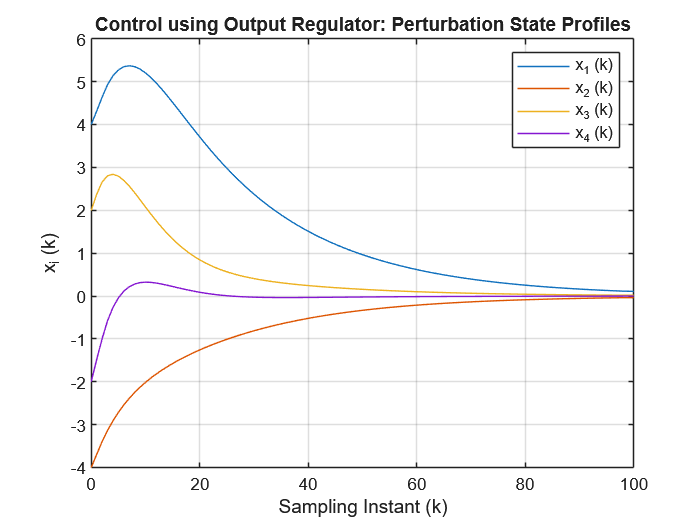

figure, plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)'), title('Control using Output Regulator: Perturbation State Profiles')

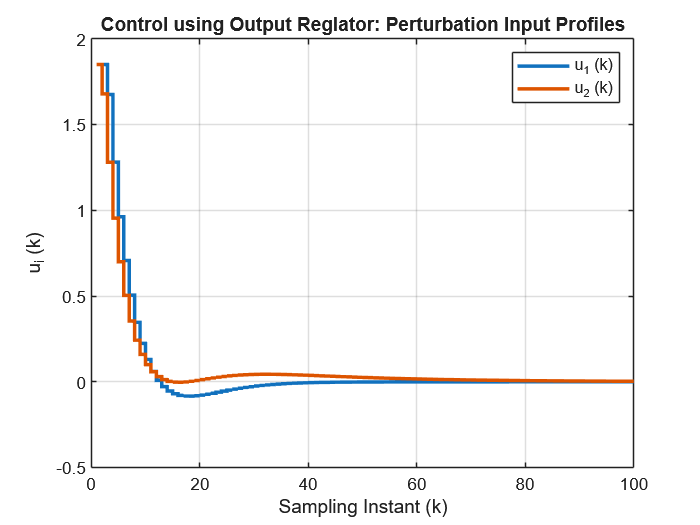

figure, stairs(uk', 'LineWidth',2), grid
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), title('Control using Output Reglator: Perturbation Input Profiles')
legend('u_1 (k)', 'u_2 (k)')

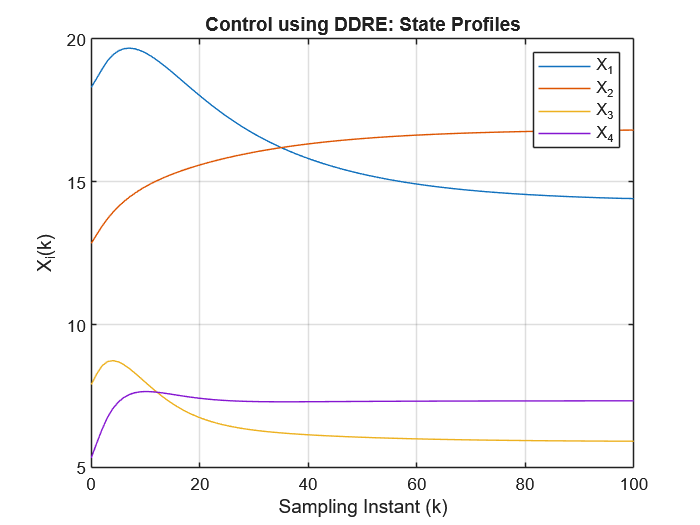

Xk = QTank.Xs + xk;
 Uk = QTank.Us + uk ;
figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('X_i(k)'), title('Control using DDRE: State Profiles')
legend('X_1', 'X_2', 'X_3', 'X_4')

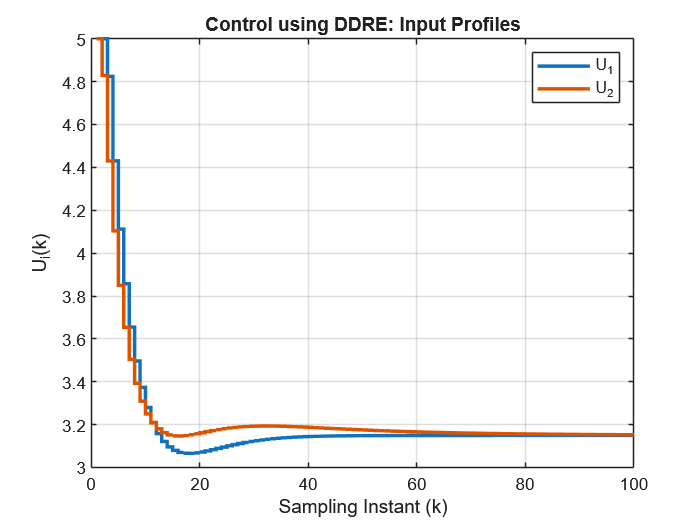

figure, stairs(Uk', 'LineWidth',2), grid
xlabel('Sampling Instant (k)'), ylabel('U_i(k)'), title('Control using DDRE: Input Profiles')
legend('U_1', 'U_2')

Let us now compare the computation times for LQR-N, LQR-inf and LQR-inf (Output Regulation). 

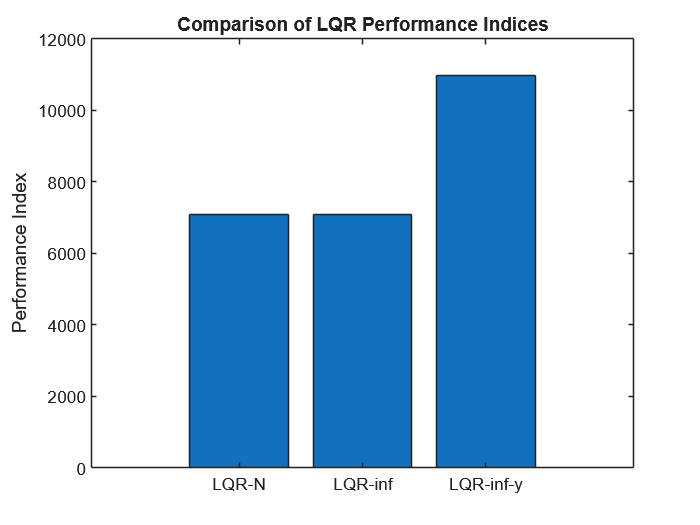

figure
bar([fval_LQRN,fval_LQRinf, fval_LQRinf_y])
xticklabels({'LQR-N', 'LQR-inf', 'LQR-inf-y'})
ylabel('Performance Index')
title('Comparison of LQR Performance Indices')

It is evident from the comparison of the performance indices that there is hardly any gain by implementing the time varying LQR gain controller. 

## Summary: Quadratic Optimal Control 

LQOC framework results in a a time varying state feedback law of the form 


$$u(k)=-G{(k) }x(k)$$
  
$$\textrm{for}\;\;k=N-1,N-2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp 0$$


The gain matrices are computed using Discrete Dynamic Riccati Equation (DDRE)


$$G(k)=(W_{u}+\Gamma ^{T}S(k+1)\Gamma )⁻¹\Gamma ^{T}S(k+1)\Phi  $$



$$S(k)=[\Phi -\Gamma G(k)]^{T}S(k+1)[\Phi -\Gamma G(k)]+W_{x}+G(k)^{T}W_{u}G(k) 
$$


Equation solved backward in time, starting from $N,N-1,\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp 1$,  $S(N)=W_{N}$. $S\left(k\right)$ is positive definite/semi-definite and symmetric at each $k$ and this condition guarantees optimality at each stage. For large N, we can use a fixed gain control law $u\left(k\right)=-G_{\infty } x\left(k\right)$ where the Algebraic Riccati Equation (ARE) is used to compute the gain matrix


$$G_{\infty } ={\left(W_u +\Gamma^T S_{\infty } \Gamma \right)}^{-1} \Gamma^T S_{\infty } \Phi$$


	
$$S_{\infty }=[\Phi -\Gamma G_{\infty }]^{T}S_{\infty }[\Phi -\Gamma G_{\infty }]+W_{x}+G_{\infty }^{T}W_{u}G_{\infty } $$


## Conclusion

In this lesson we have learnt about the Finite Horizon and Infinite Horizon formulation of LQ optimal  controller. Both controllers use a quadratic cost function, but the weighting of the cost function may differ based on the desired behavior within the specific time horizon. While both use the Riccati equation to solve for the optimal control gains, the finite horizon solution involves a time-varying Riccati equation, while the infinite horizon solution converges to Algebraic Riccati equation and yields a fixed gain control law. There is hardly any performance loss when the resulting fixed gain controller is used. Thus, we will continue to use infinite horizon formulation in the rest of the course.  In the next lesson we will further study the [stability analysis of the infinite horizon controller](matlab:open('./L02_StabiltyAnalysis_of_Discrete_LinearSystems.mlx')). 

## References

- Trentelman, H. (2013). Linear Quadratic Optimal Control. In: Baillieul, J., Samad, T. (eds) Encyclopedia of Systems and Control. Springer, London. https://doi.org/10.1007/978-1-4471-5102-9_201-3

-  Astrom : Astrom, K. J. and B. Wittenmark, Computer Controlled Systems, Prentice Hall, 1990.

- Franklin : Franklin, G. F. and J. D. Powell, Digital Control of Dynamic Systems, Addison-Wesley, 1989.

- Goodwin : Goodwin, G., Graebe, S. F., Salgado, M. E., Control System Design, Phi Learning, 2009.